% Experiment on the Cascaded watertanks benchmark
%
% References
% ---------
%
% A Tensor Network Kalman filter with an application in recursive MIMO Volterra system identification
% 2016, Kim Batselier, Zhongming Chen, Ngai Wong
% 

clear all
close all
clc

%for reproducibility
rng(1);

load('cascaded\dataBenchmark')


Preprocessing Data

tic

% Normalize the input and output training data to [0 1]
input = uEst/7;
output = yEst/10-0.1;

% plot(input)
% plot(output)
% 
% histogram(input)
% histogram(output)

% Normalize the input and output test data to [0 1]
tinput = uVal/7 ;
toutput = yVal/10-0.1;

% Choose the lags for the input and output
% inlags=[1 2];
% outlags=[0 1 2 3 4 8 16];
% outlags=[0 1 2 3 4];

inlags=[1 2 3 4 8 16 32];
outlags=[0 1 2 3 4 8 16 32];

% %  for prediction
% inlags=[1 2];
% outlags=[0 1 2 3 4];


Split test and training set

% % Features are lagged inputs and outputs

[featurez,zeta,tfeaturez,yt] = lagfeatures(input,tinput,output,toutput,inlags,outlags);

Construct B-spline basis vectors


[N, d]=size(featurez); % Number of samples and features

n = 3;                  %Degree B-spline
m = 1;                  %Number of knot intervals
In = n+m;               %Number of B-splines



Initialize tensor train

% Choose TT-ranks
maxrank = 8;

% % for prediction
% maxrank = 5;

r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));


Cross validation for tuning lambda

difforder=1;

LAM = logspace(-5,-9,15);

% % for prediction
% LAM = logspace(-8,-3,15);

MAXITR = d;

for period = 1:numel(LAM)

    lambda = LAM(period);
    
for trial = 1:3
% selc= setdiff(1:length(featurez),(trial-1)*252+1:trial*252);
% selc = randperm(length(featurez),900);

tselc = (1:200)+(trial-1)*200;
selc = setdiff(1:length(featurez),tselc);

fold = featurez(selc,:);
tfold = featurez(tselc,:);

Nf= size(fold, 1);

unf = basisvectors(fold,n,m);

for initial = 1:1
[TNf,Vmf,Vpf] = initTT(unf,r,d);

[TN,~,~,~,~] = optimTT(TNf,Vmf,Vpf,unf,zeta(selc),MAXITR,[],lambda,difforder);

[simoutput] = simnarx(TN,input(tselc),output(tselc),inlags,outlags,n,m);
RMSE_S(period,trial,initial) = sqrt(immse(10*output(tselc),10*simoutput));

yhat = evalspline(TN,tfold,n,m);
RMSE_P(period,trial,initial) = sqrt(immse(10*yhat,10*zeta(tselc)));
end
end
end


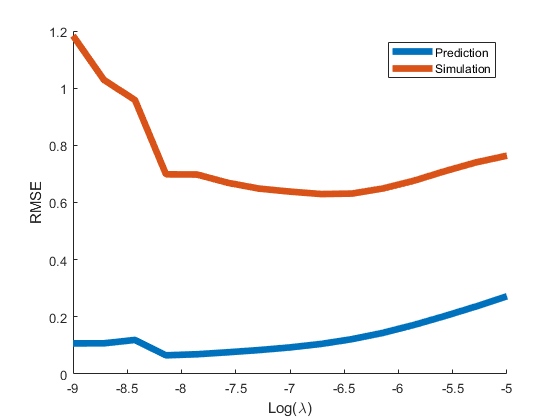


figure
hold on
% plot(RMSE_P)
% plot(RMSE_S)
plot(log10(LAM),squeeze(mean(RMSE_P,2)),"LineWidth",5)
% plot(squeeze(median(RMSE_P,2)),"LineWidth",5)
plot(log10(LAM),mean(RMSE_S,2),"LineWidth",5)
hold off
legend('Prediction', 'Simulation')
xlabel('Log(\lambda)')
ylabel('RMSE')


% scatter(mean(RMSE_P,2),mean(RMSE_S,2))
% scatter(median(RMSE_P,2),median(RMSE_S,2))

% [~,hyp] = min(median(median(RMSE_P,2),3));
% [~,hyp] = min(mean(mean(RMSE_P,2),3));
[~,hyp] = min(mean(mean(RMSE_S,2),3));
lambda = LAM(hyp)

lambda = 1.9307e-07



% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);

% Initialize Tensor Train and Vp and Vm
[TN,Vm,Vp] = initTT(un,r,d);


Optimize TT cores


% lambda = 4.6416e-07 %from cross val
% lambda = 2e-07

MAXITR = d;


tic
[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,[],lambda,difforder);
toc

Elapsed time is 2.212729 seconds.


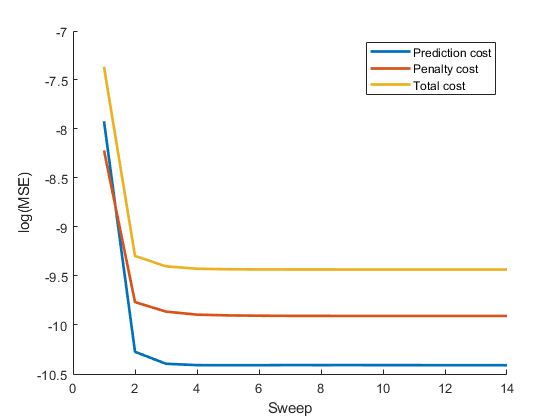

figure
hold on
plot(log(res1),'linewidth',2)
plot(log(res2),'linewidth',2)
plot(log(res1+res2),'linewidth',2)
hold off
legend('Prediction cost', 'Penalty cost', 'Total cost')
xlabel('Sweep')
ylabel('log(MSE)')

Prediction Test data


yhat = evalspline(TN,tfeaturez,n,m);
erboi = (yhat-yt);
% histogram((erboi)');
VAF = 1-var(erboi)/var(yt)

VAF = 0.9979

RMSE_Pt = sqrt(immse(10*yhat,10*yt))

RMSE_Pt = 0.0969

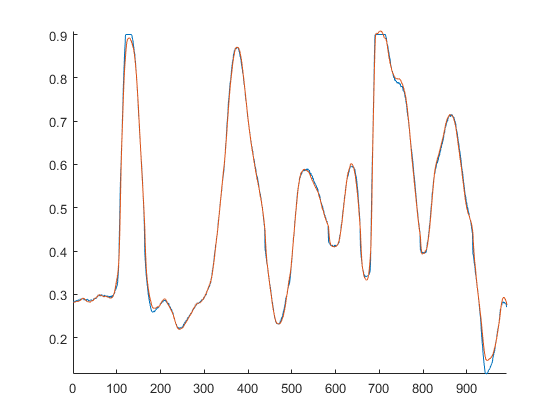


%  Visualize errors

figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 inf -inf inf])

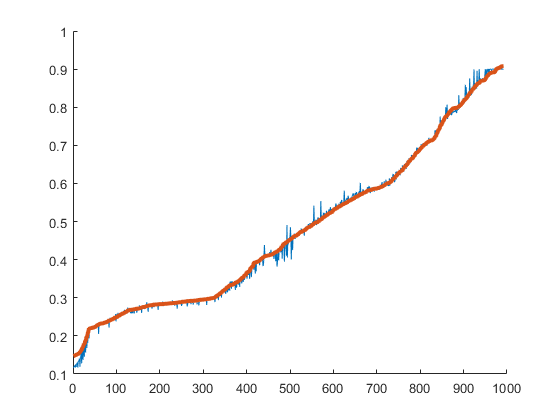


[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

Simulation Test data

[simoutput] = simnarx(TN,tinput,toutput,inlags,outlags,n,m);

fig = figure

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


hold on
plot(10*toutput+1,'linewidth',2)
plot(10*simoutput+1,'linewidth',2)
hold off
beginz = max(outlags(end),inlags(end)) +1;
RMSE_St = sqrt(immse(10*toutput(beginz:end),10*simoutput(beginz:end)))

RMSE_St = 0.3018

toc

Elapsed time is 3.629524 seconds.


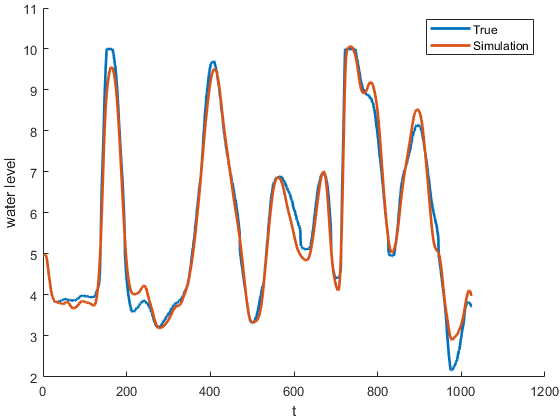

legend('True', 'Simulation')
xlabel('t')
ylabel('water level')

T = get(gca,'tightinset');
set(gca,'position',[T(1) T(2) 1-T(1)-T(3) 1-T(2)-T(4)]);
print(fig,'figures/cascadesim','-depsc')

Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %compression ratio

Compression: 1.061e-05



testet = sqrt(immse(10*toutput(beginz+1:end),10*toutput(beginz:end-1)))

testet = 0.1034